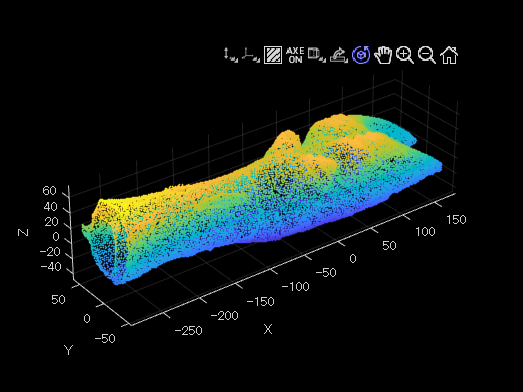

file = uigetfile('.stl');
ptCloud = import3Dmodel(file, true);

newPoint = ptCloud

newPoint =   pointCloud のプロパティ:

     Location: [39107×3 double]
        Count: 39107
      XLimits: [-292.0085 184.5884]
      YLimits: [-55.3673 62.9171]
      ZLimits: [-48.1140 76.3615]
        Color: []
       Normal: []
    Intensity: []


t = 1

t = 1

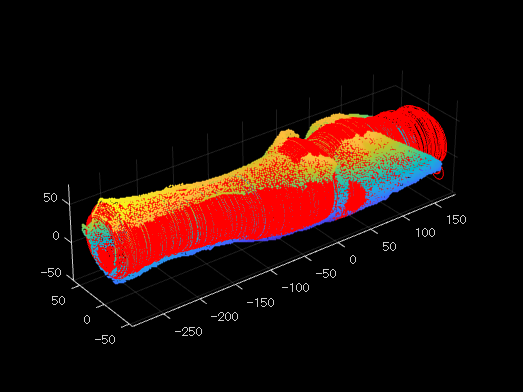

Data = sliceCircleRho(newPoint, 'x', t, true);

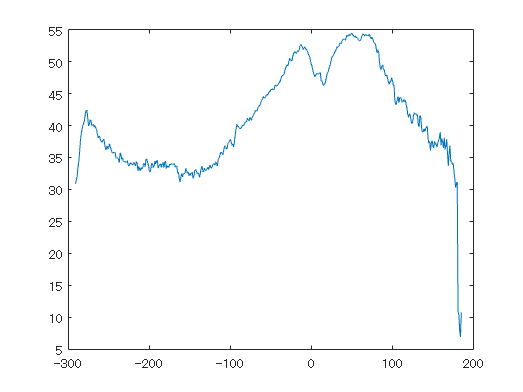

figure();
x = Data(:,1);
center_x = Data(:,3);
center_y = Data(:,4);
rho = Data(:,5);
figure();
plot(x, rho);

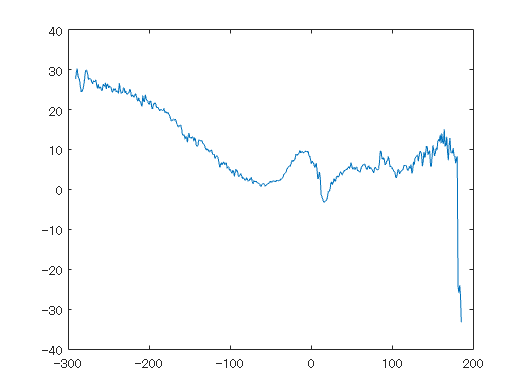

% plot(x, center_x)
plot(x, center_y)


sp = newPoint.Location;
s = sp(sp(:,1) > -100 & 40 > sp(:,1), :)

s =   -36.1483  -34.2249   33.3913
  -35.3010  -35.0015   32.7815
  -34.4714  -34.5212   34.6957
  -31.2200  -37.9429   28.7411
  -30.4909  -37.0368   31.7988
  -34.1698  -36.4983   30.0875
  -29.7502  -35.7403   36.1056
  -31.4286  -34.6977   37.0507
  -30.9503  -36.1063   34.4993
  -35.3248  -33.6982   35.7898


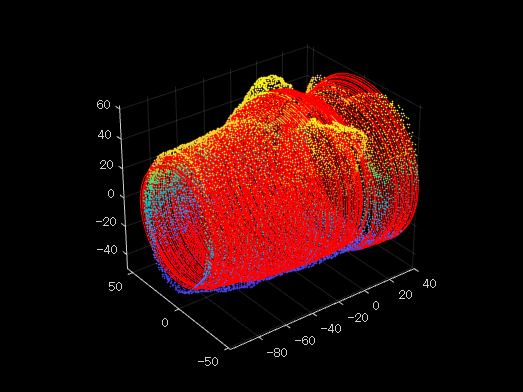

sPoint = pointCloud(s);
sData = sliceCircleRho(sPoint, 'x', t, true);

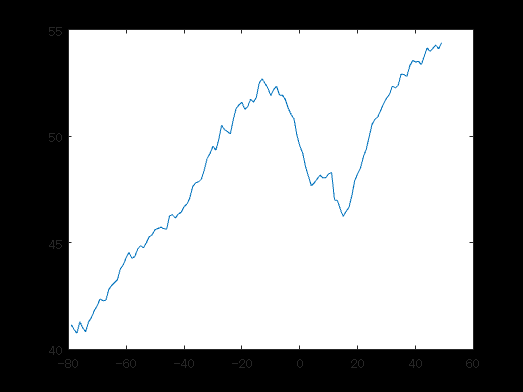

[maxrho, I] = max(rho);
cData = Data(Data(:,1)>x(I)-130 & x(I) > Data(:,1),:);
cx = cData(:,1);
crho = cData(:,5);
% c_y = cData(:,4);
plot(cx, crho);

n = 4;
n1 = 0

n1 =      0


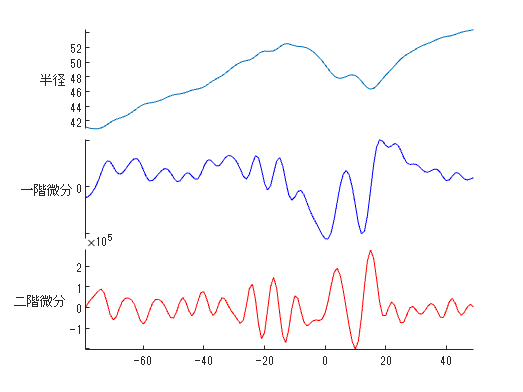

Wn = 0.3;
[rho_y, rho_v1, rho_v2] = filterAnddiff(crho, n, Wn);
figure('Name','Filtering');
% plot(cx,rho_y);
% plot(cx, rho_v1);
% plot(cx, rho_v2)
% [cy_y, cy_v1, cy_v2] = filterAnddiff(c_y, n, Wn);
% figure('Name', 'center_y')
% plot(cx, cy_y);
newLabels = ["半径", "一階微分", "二階微分"];
s = stackedplot(cx, [rho_y, rho_v1, rho_v2], 'DisplayLabels',newLabels, 'Color','r');
s.LineProperties(1).Color = '#0072BD';
s.LineProperties(2).Color = 'b';
s.LineProperties(3).Color = 'r';


TF = islocalmin(rho_v1, 'MaxNumExtrema',1 );
cx(TF)

ans =    0.991540431976318


cutPos = 15;
recutData = cData(cData(:,1) < cx(TF)-cutPos, :);
srx = recutData(:,1);
rRho = recutData(:,3);
[ysr, v1_sr, v2_sr] = filterAnddiff(rRho, n, Wn);

smTF = islocalmax(v1_sr, 'MinProminence',50, 'MaxNumExtrema',2);
% plot(srx, v1_sr, srx(smTF), v1_sr(smTF), 'ro');
% ylabel('一階微分')
localMaxSet = [srx(smTF) v1_sr(smTF)];
disp(localMaxSet);

   1.0e+02 *

  -0.690084595680237   0.401428080545292
  -0.400084595680237   1.086437208513209



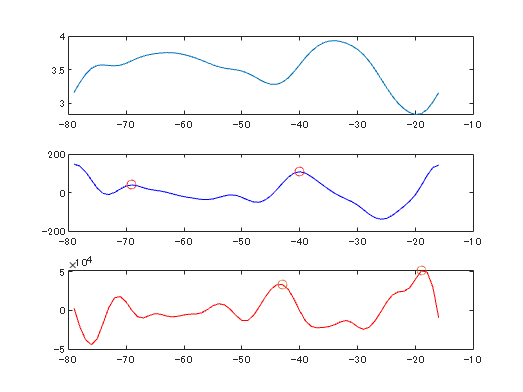

[maxPoint, I] = max(localMaxSet(:,2));
rx_extream = localMaxSet(I);

smTF2 = islocalmax(v2_sr, 'MinProminence',10000, 'MaxNumExtrema',2);
% plot(srx, v2_sr, 'r',srx(smTF2), v2_sr(smTF2), 'o');
% ylabel('二階微分')
localMaxSet2 = [srx(smTF2) v2_sr(smTF2)]; 
[max2, I2]  = max(localMaxSet2(:,2));
rx_ex2 = localMaxSet2(I2);

figure('Name', '第二探索');
subplot(3, 1,1);
plot(srx, ysr);
subplot(3,1,2);
% plot(cx,v1,'b',locv1,pkv1, 'o');
plot(srx,v1_sr,'b',srx(smTF),v1_sr(smTF), 'ro');
subplot(3, 1, 3);
plot(srx, v2_sr,'r',srx(smTF2), v2_sr(smTF2), 'o');

samplingWidth = 5;
samplemin = rx_extream-samplingWidth

samplemin =  -45.008459568023682


samplemax = rx_extream

samplemax =  -40.008459568023682




cent = rx_ex2

cent =  -19.008459568023682


samplemin2 = cent-(samplingWidth/2);
samplemax2 = cent+(samplingWidth/2);
% plot(srx, v2_sr, 'r',srx(smTF2), v2_sr(smTF2), 'o', srx, samplemin2, '*', srx, samplemax2, '*');

l = samplemax2-samplemin2

l =      5


sampleData = recutData(recutData(:,1) > samplemin & samplemax > recutData(:,1),:);
sampleDataf2 =  recutData(recutData(:,1) > samplemin2 & samplemax2 > recutData(:,1),:);
Circum = mean(sampleData(:,2));
Cir_f2 = mean(sampleDataf2(:,2));

fprintf('%f < dt < %fの時, 平均周囲長は %f \n',samplemin, samplemax, Circum);

-45.008460 < dt < -40.008460の時, 平均周囲長は 294.780629 


fprintf('%f < dt < %fの時, 平均周囲長は %f \n',samplemin2, samplemax2, Cir_f2);

-21.508460 < dt < -16.508460の時, 平均周囲長は 333.754405 


sP = newPoint.Location;
idx = 1

idx =      1


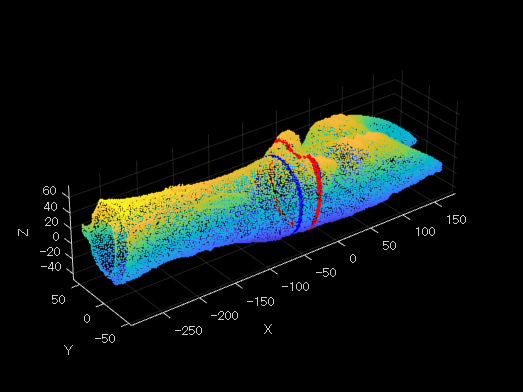

samplePoint = sP(sP(:,idx) > samplemin & sP(:,idx) < samplemax, :);
samplePointf2 = sP(sP(:,idx) > samplemin2 & sP(:,idx) < samplemax2, :);
pcshowWithAxes(newPoint, 'marking1');
hold on;
pcshow(samplePoint, 'b', 'AxesVisibility', 'on');
% hold off;
% pcshowWithAxes(newPoint, 'marking2');
% hold on;
pcshow(samplePointf2, 'r','AxesVisibility', 'on');
hold off;